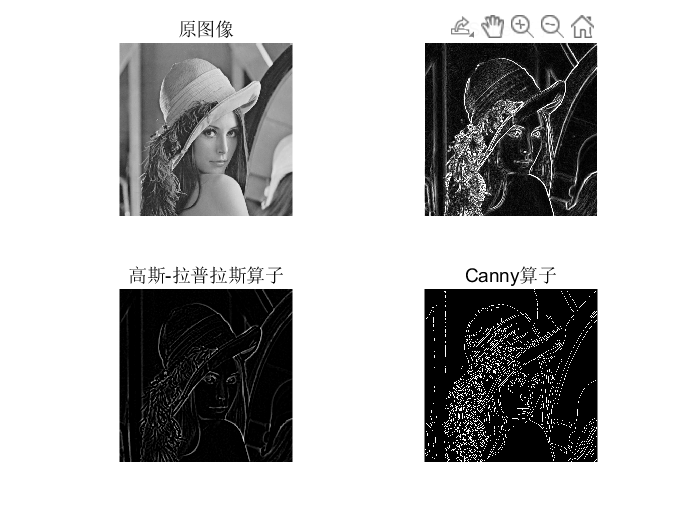

% 读取Lenna图像并转换为灰度图像
img = imread('clena.jpeg');
if size(img, 3) == 3
    img = rgb2gray(img);
end
img = double(img)/255;

% Sobel算子
sobel_h = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
sobel_v = [-1, -2, -1; 0, 0, 0; 1, 2, 1];
sobel_h_img = imfilter(img, sobel_h);
sobel_v_img = imfilter(img, sobel_v);
sobel_img = sqrt(sobel_h_img.^2 + sobel_v_img.^2);

% 高斯-拉普拉斯算子
gaussian_img = imgaussfilt(img, 2);
laplacian_img = del2(gaussian_img);
laplacian_img = laplacian_img/max(abs(laplacian_img(:)));

% Canny算子
canny_img = edge(img, 'Canny');

% 显示结果
figure;
subplot(2, 2, 1), imshow(img), title('原图像');
subplot(2, 2, 2), imshow(sobel_img), title('Sobel算子');
subplot(2, 2, 3), imshow(laplacian_img), title('高斯-拉普拉斯算子');
subplot(2, 2, 4), imshow(canny_img), title('Canny算子');

Sobel算子首先将图像分别与横向和纵向的卷积核进行卷积，得到了横向和纵向的梯度值。然后，我们计算各像素点的梯度幅度，作为其边缘强度。

高斯-拉普拉斯算子是先对原始图像进行高斯滤波，然后再对滤波后的图像使用拉普拉斯算子进行边缘检测。在本代码中，我们使用了Matlab内置的���2*d**e**l*2函数计算拉普拉斯算子，得到的是一个灰度图像，需要通过对所有像素的绝对值进行标准化来显示。

Canny算子是一种在提取图像边缘时使用的多阶段算法，它首先使用高斯滤波器平滑图像，然后计算图像梯度的幅值和方向。接着，算法根据梯度方向将像素点分类为强边缘、弱边缘或非边缘。最后，算法根据非极大值抑制和双阈值处理来确定边缘强度。

三种算子的区别主要在于以下几个方面：

- Sobel算子是最基本的算子，它对图像的梯度进行计算，而不考虑边缘强度的方向和是否是连续的边缘。

- 高斯-拉普拉斯算子是使用高斯平滑过滤器平滑图像后，对平滑后的图像使用拉普拉斯算子进行边缘检测，主要考虑较长的边缘和连续的线条。

- Canny算子是一种综合了多种技术的边缘检测算法，能够精确检测到不同方向、强度和形状的边缘，同时能够减小噪声和非边缘响应。

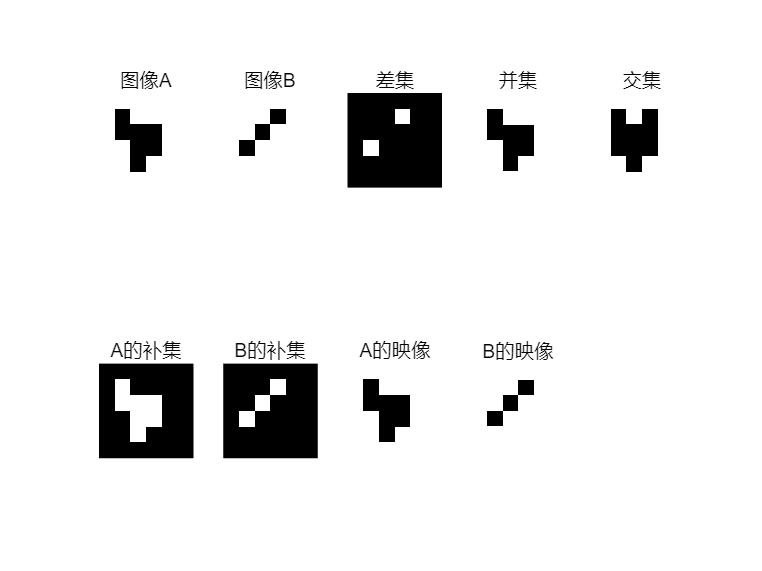

clf
A=[1 1 1 1 1 1;
   1 0 1 1 1 1;
   1 0 0 0 1 1;
   1 1 0 0 1 1;
   1 1 0 1 1 1;
   1 1 1 1 1 1];
B=[1 1 1 1 1 1;
   1 1 1 0 1 1;
   1 1 0 1 1 1;
   1 0 1 1 1 1;
   1 1 1 1 1 1;
   1 1 1 1 1 1];
figure; % 新建绘图窗口
subplot(2,5,1), imshow(A); title("图像A");
subplot(2,5,2), imshow(B); title("图像B");

% 计算交集
intersect = A .* (A == B);

% 求并集
union = A + (B .* ~(A ~= B));

% 求差集
difference_A_B = A .* (A ~= B);
difference_B_A = B .* (A ~= B);

% 计算A的补集和B的补集
complement_A = imcomplement(A); % A的补集
complement_B = imcomplement(B); % B的补集

% 计算A和B的映像
map_A = A.^2;
map_B = B.^3;

% 显示结果
subplot(2,5,3), imshow(difference_A_B); title("差集");
subplot(2,5,4), imshow(union); title("并集");
subplot(2,5,5), imshow(intersect); title("交集");
subplot(2,5,6), imshow(complement_A); title("A的补集");
subplot(2,5,7), imshow(complement_B); title("B的补集");
subplot(2,5,8), imshow(map_A); title("A的映像");
subplot(2,5,9), imshow(map_B); title("B的映像");